# Rocky Parameter Identification

## Motor Constants

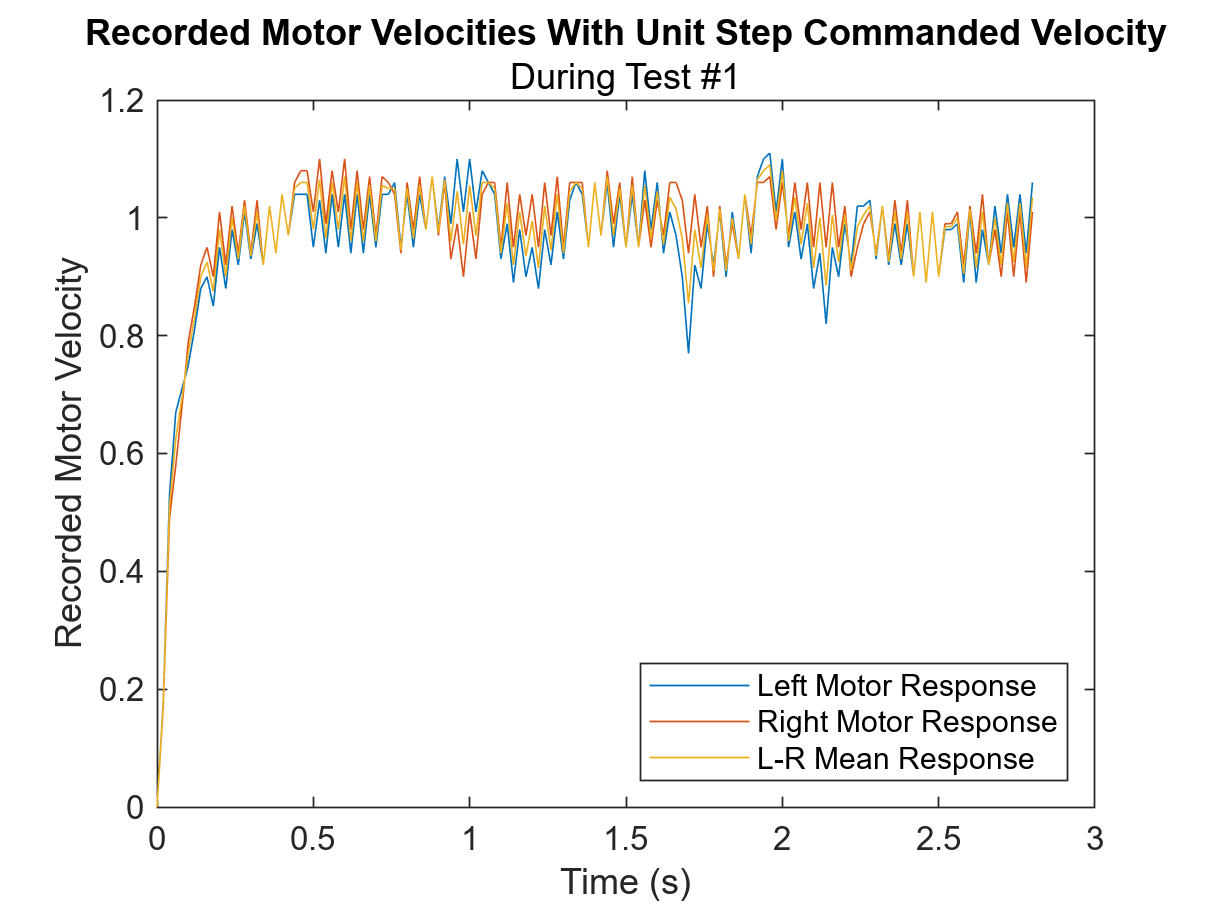

Ks = [];
taus = [];

% Calculate K and tau from first test
[t, L_vel, R_vel, V_mean] = get_vel_data('output_floor_3s.txt', 141, 0.02, true);
subtitle("During Test #1")

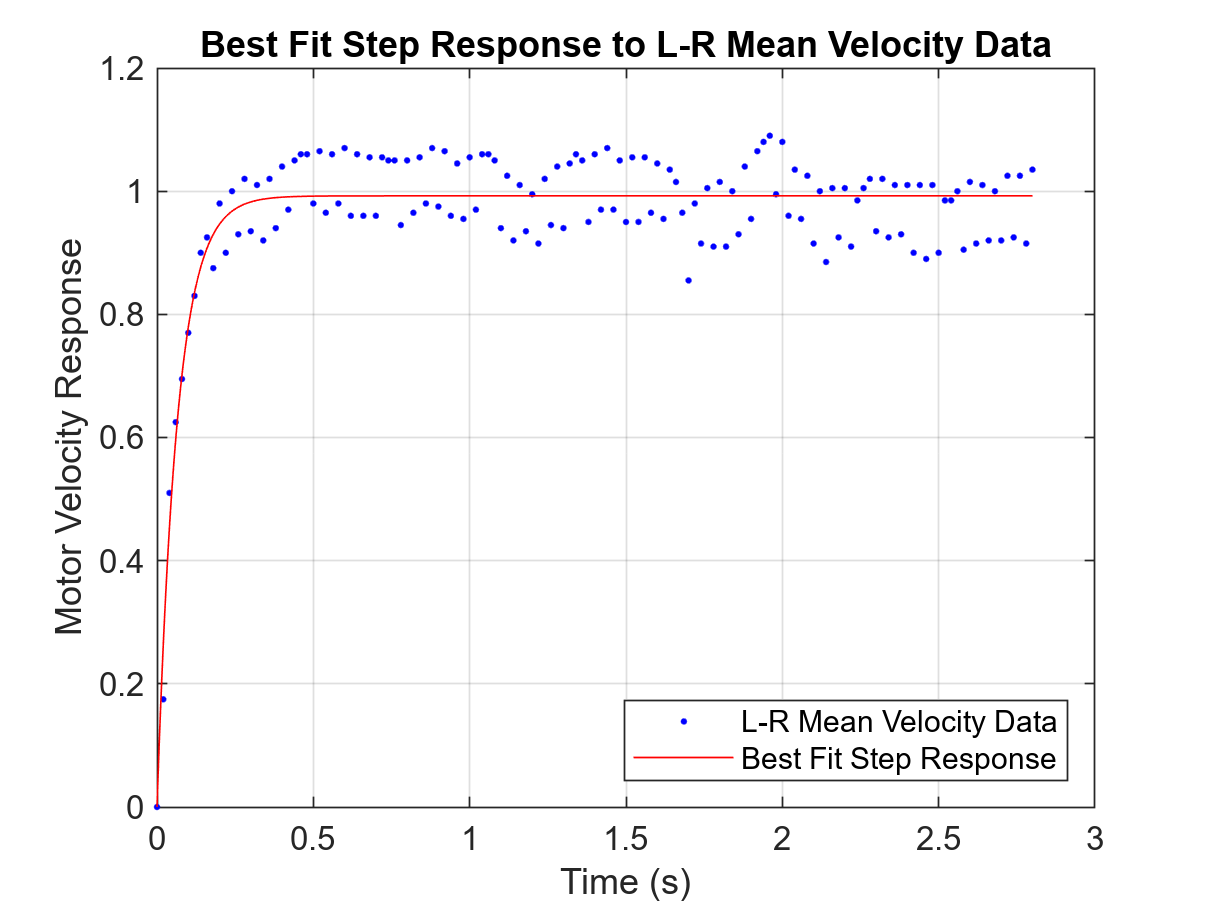

meanFit =      General model:
     meanFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003308  (0.003277, 0.003339)
       tau =     0.06508  (0.05714, 0.07303)

meanFit = createStepResponseFit(t, V_mean)

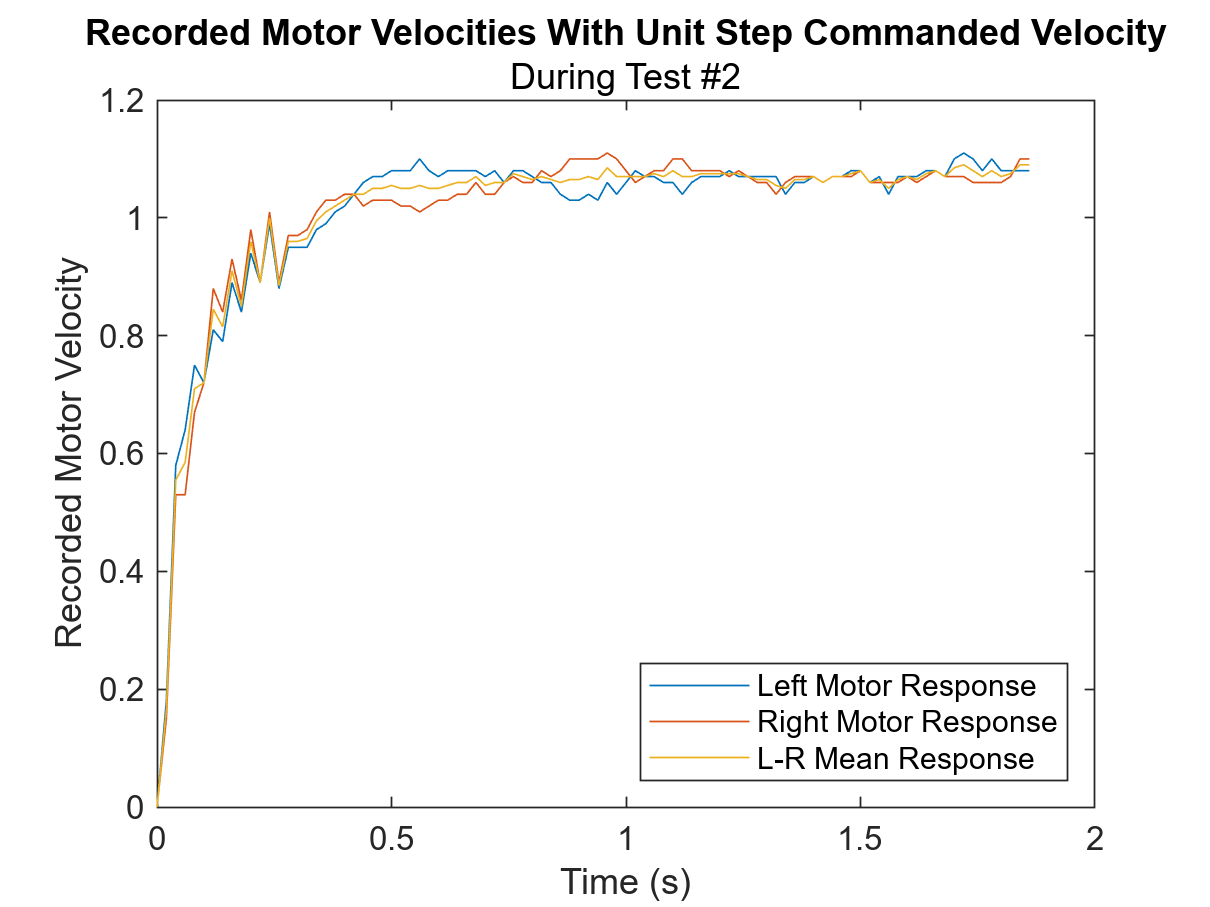

taus = [taus; meanFit.tau];
Ks = [Ks; meanFit.K];

% Calculate K and tau from second test
[t, L_vel, R_vel, V_mean] = get_vel_data('output_floor_2s.txt', 94, 0.02, true);
subtitle("During Test #2")

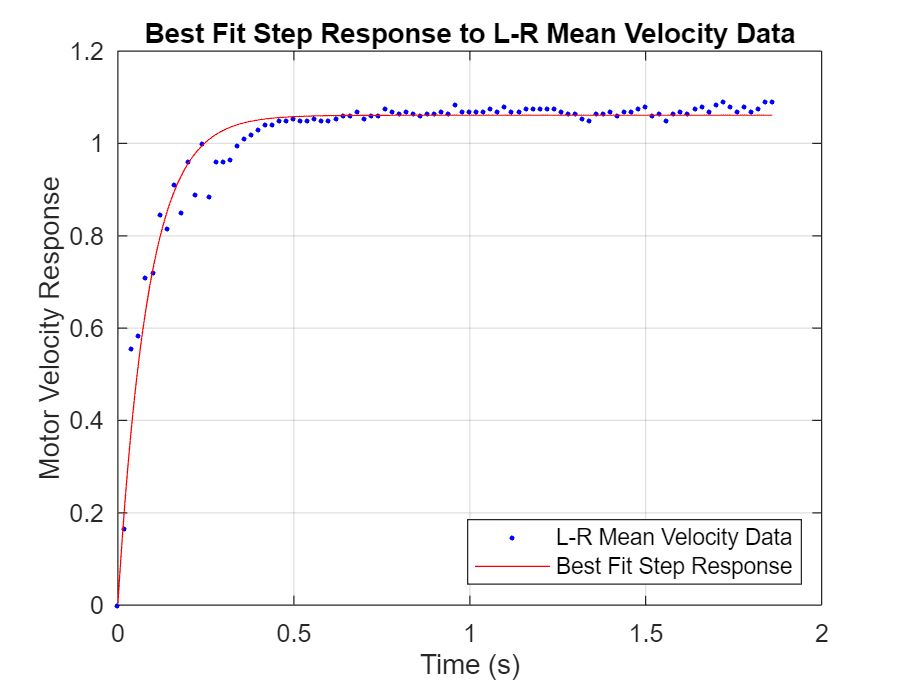

meanFit =      General model:
     meanFit(x) = 300*K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =    0.003537  (0.003513, 0.003562)
       tau =     0.08621  (0.08083, 0.09159)

meanFit = createStepResponseFit(t, V_mean)

taus = [taus; meanFit.tau];
Ks = [Ks; meanFit.K];

Ks

Ks =     0.0033
    0.0035


taus

taus =     0.0651
    0.0862


% Average K and tau values
K = mean(Ks)

K = 0.0034

tau = mean(taus)

tau = 0.0756


% Save K and tau for later use
save('MotorResponse3-2-23', 'tau', 'K', 'taus', 'Ks')

## Natural Frequency and Effective Length

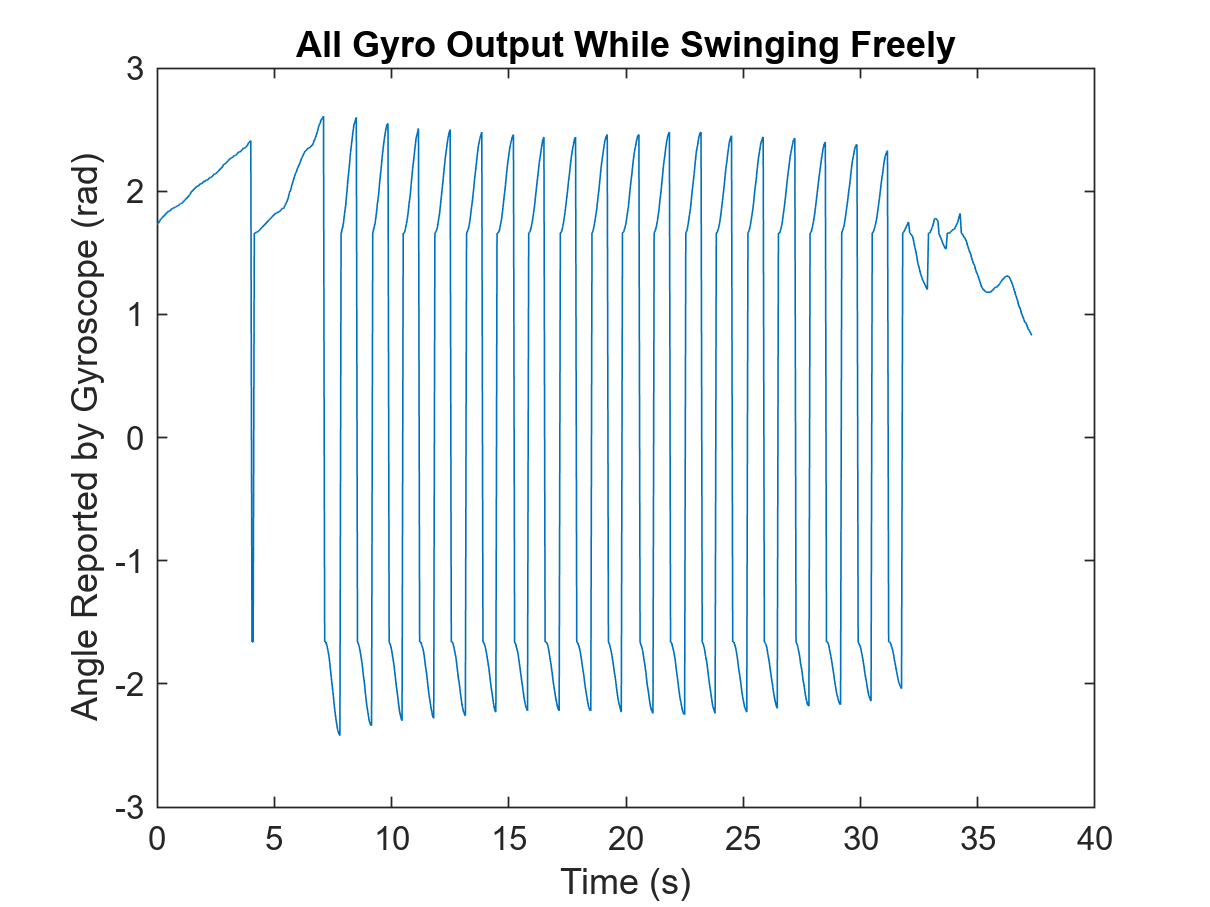

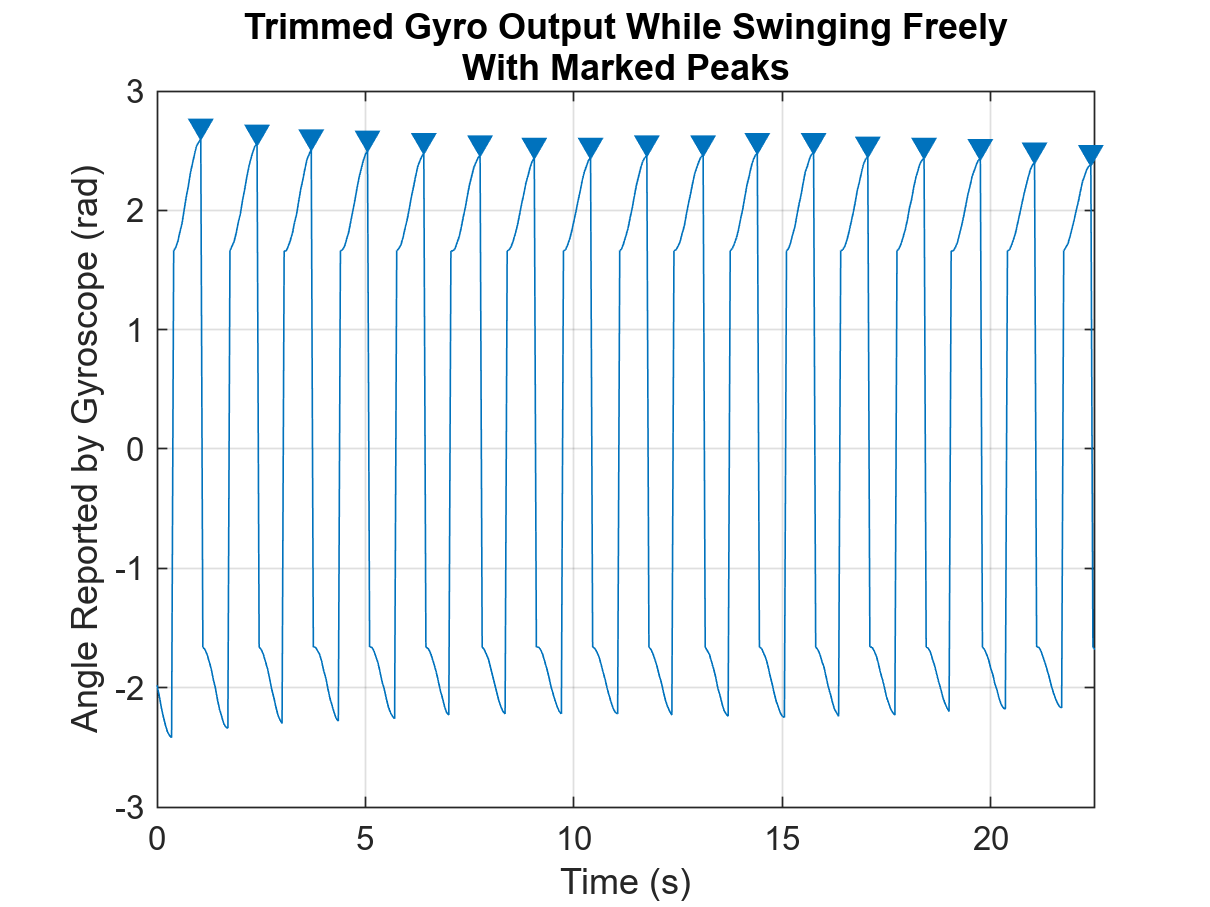

wn1 = 4.7087

% Calculate natural frequency and effective length from first test
wn1 = find_natural_freq('output_gyro.txt', 150, 600, 0.05, true)

l_eff1 = 9.81/wn1^2

l_eff1 = 0.4425


% Calculate natural frequency and effective length from second test
wn2 = find_natural_freq('output_gyro1.txt', 200, 550, 0.05, false)

wn2 = 4.7767

l_eff2 = 9.81/wn2^2

l_eff2 = 0.4299


% Average natural frequency and effective length across tests
wn = mean([wn1, wn2])

wn = 4.7427

l_eff = mean([l_eff1, l_eff2])

l_eff = 0.4362

# Functions

## Motor Constants Derivation Functions

function [t, L_vel, R_vel, V_mean] = get_vel_data(filename, end_idx, delta_t, disp)
    % Read data
    data = readtable(filename);
    L_vel = data.Var1;
    R_vel = data.Var2;

    % Trim end if necessary
    L_vel = L_vel(1:end_idx);
    R_vel = R_vel(1:end_idx);

    % Clean data
    R_vel = erase(R_vel,';');
    R_vel = cellfun(@str2num,R_vel);

    % Make t
    t = 0:delta_t:10;
    t = t(1:length(L_vel))';

    % Average L and R velocities
    V_mean = (L_vel + R_vel)/2;

    if disp
        figure()
        plot(t, L_vel)
        hold on
        plot(t, R_vel)
        plot(t, V_mean)
        legend('Left Motor Response', 'Right Motor Response', 'L-R Mean Response', 'Location', 'southeast')
        title("Recorded Motor Velocities With Unit Step Commanded Velocity")
        ylabel("Recorded Motor Velocity")
        xlabel("Time (s)")
    end
end

function [fitresult, gof] = createStepResponseFit(t, vel)
    %CREATEFIT(T,V_MEAN)
    %  Create a fit.
    %
    %  Data for 'VStepResponse' fit:
    %      X Input : t
    %      Y Output: V_mean
    %  Output:
    %      fitresult : a fit object representing the fit.
    %      gof : structure with goodness-of fit info.
    %
    %  See also FIT, CFIT, SFIT.
    
    %  Auto-generated by MATLAB on 02-Mar-2023 10:36:39
    
    
    %% Fit: 'VStepResponse'.
    [xData, yData] = prepareCurveData( t, vel );
    
    % Set up fittype and options.
    ft = fittype( '300*K*(1-exp(-x/tau))', 'independent', 'x', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.StartPoint = [0.913375856139019 0.0975404049994095];
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft, opts );
    
    % Plot fit with data.
    figure( 'Name', 'VStepResponse' );
    h = plot( fitresult, xData, yData );
    legend( h, 'L-R Mean Velocity Data', 'Best Fit Step Response', 'Location', 'southeast', 'Interpreter', 'none' );
    % Label axes
    xlabel( 'Time (s)', 'Interpreter', 'none' );
    ylabel( 'Motor Velocity Response', 'Interpreter', 'none' );
    title("Best Fit Step Response to L-R Mean Velocity Data")
    grid on
end

## Natural Frequency Derivation Function

function wn = find_natural_freq(gyro_data_file, start_idx, end_idx, delta_t, disp)
    % Get angles from file
    gyrodata = readtable(gyro_data_file);
    angles = gyrodata.Var1;
    t = 0:delta_t:50;
    t = t(1:length(angles))';
    
    % Plot all data if desired
    if disp 
        figure
        plot(t, angles)
        title("All Gyro Output While Swinging Freely")
        ylabel("Angle Reported by Gyroscope (rad)")
        xlabel("Time (s)")
    end

    % Trim data to relevant area
    angles = angles(start_idx:end_idx);
    t = t(1:length(angles));

    % Plot peaks
    if disp
        figure
        findpeaks(angles, t)
        title(["Trimmed Gyro Output While Swinging Freely", "With Marked Peaks"])
        ylabel("Angle Reported by Gyroscope (rad)")
        xlabel("Time (s)")
    end

    % Find times of peaks
    [pks, times_pks] = findpeaks(angles, t);
    
    % Find period of peaks
    period_sd = std(diff(times_pks));
    period = mean(diff(times_pks));

    % Find natural frequency
    wn = 2*pi/period;
end